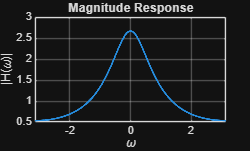

B = 1;
A = [1 -3/4 1/8];

% frequency grid
W = -pi:0.001:pi;          % frequencies in [-π, π]

% frequency response
H = freqz(B, A, W);

% magnitude and phase
mag = abs(H);
pha = unwrap(angle(H));

% path to Obsidian Resources folder
obsidian_path = 'C:\Users\Mads2\DTU\Obsidian\Resources\';

% --- Magnitude Response ---
figure;
plot(W, mag, 'LineWidth', 1.5), grid on
xlim([-pi pi])
xlabel('\omega')
ylabel('|H(\omega)|')
title('Magnitude Response')

exportgraphics(gcf, fullfile(obsidian_path, 'MagnitudeResponse.png'), 'Resolution', 300);

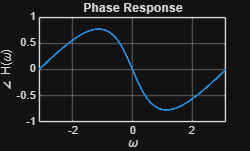


% --- Phase Response ---
figure;
plot(W, pha, 'LineWidth', 1.5), grid on
xlim([-pi pi])
xlabel('\omega')
ylabel('\angle H(\omega)')
title('Phase Response')

exportgraphics(gcf, fullfile(obsidian_path, 'PhaseResponse.png'), 'Resolution', 300);